## Environmental Data analysis and Statistical Learning

## Exercise 5 – Bootstrap confidence intervals

## Ka Hei Pinky, Chow

### Loading Data

clear

load ue_05_bootstrap_data
whos

  Name                              Size             Bytes  Class       Attributes

  DateTime                      38849x1             310793  datetime              
  TETA_S_D_VWC_10_A_nogaps      38849x1             310792  double                



VWC = TETA_S_D_VWC_10_A_nogaps;

### Plotting

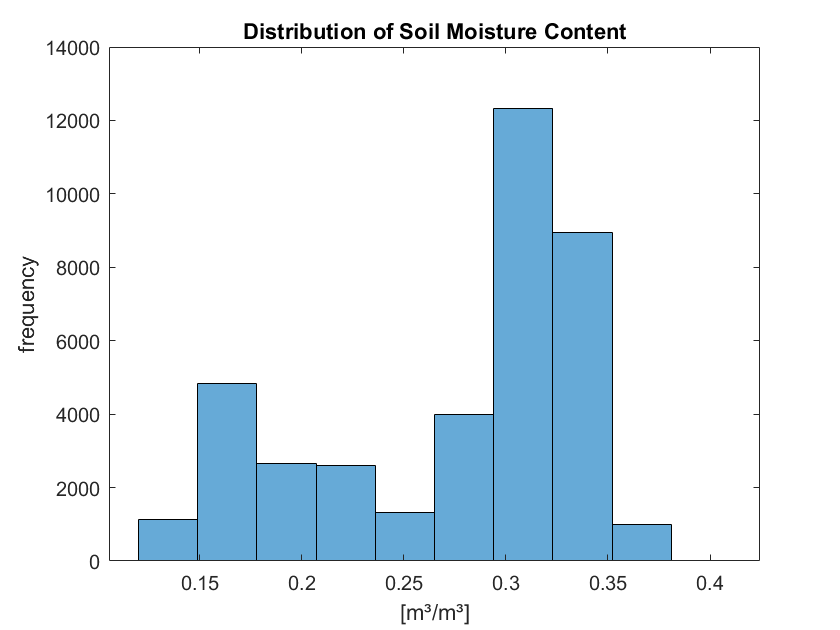

histogram(VWC,10)
xlabel("[m³/m³]")
ylabel("frequency")
title("Distribution of Soil Moisture Content")

### Best estimate for the mean

display("Mean value of soil moisture content: " + mean(VWC) +" [m³/m³]")

    "Mean value of soil moisture content: 0.27472 [m³/m³]"



### Uncertainty estimate

Calculate Confidence Level

alpha = [0.1, 0.01, 0.001]

alpha =     0.1000    0.0100    0.0010


confl = zeros(2,length(alpha));
[confl(:,1)] = bootci(10000,{@mean,VWC},'alpha',alpha(1));
[confl(:,2)] = bootci(10000,{@mean,VWC},'alpha',alpha(2));
[confl(:,3)] = bootci(10000,{@mean,VWC},'alpha',alpha(3))

confl =     0.2742    0.2738    0.2737
    0.2753    0.2756    0.2758


Histogram of all bootstrap estimates

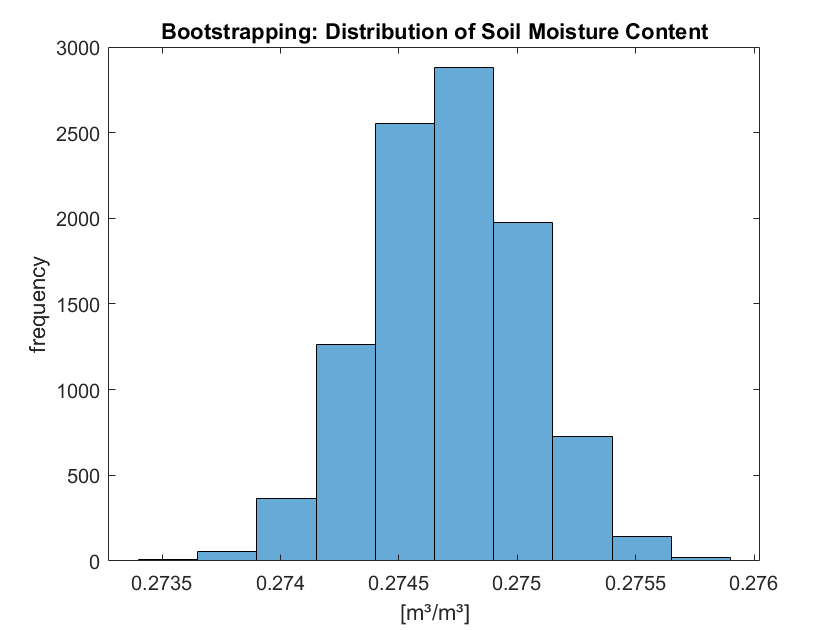

bootstat = sort(bootstrp(10000,@mean,VWC));
histogram(bootstat,10)
xlabel("[m³/m³]")
ylabel("frequency")
title("Bootstrapping: Distribution of Soil Moisture Content")

### Results Comparison

The results of confidence level calculation from bootstraping is compared to the results from the one-sample t-test. As the bootstrap repetitions increases, the confience level limits of the three significant levels (0.1, 0.01, 0.001) approach the values obtained in the t-test. With bootstrap repetitions of 10000, the confidence level limits are close to exactly the same with the values in t-test.

Alpha        0.1         0.01      0.001

Lower    0.2742    0.2738   0.2737

Upper    0.2753    0.2756  0.2758